# Augmented Neural Network in the Field-Oriented Control (FOC)

In this exercise, we will collect data from the speed regulation of a surface-mounted permanent magnet synchronous motor (PMSM) using field-oriented control (FOC). FOC is a control scheme in which a d-q coordinates reference frame that is locked to the motor flux space vector is used to achieve decoupling between the motor flux and torque. Consequently, they can be separately controlled by stator direct-axis and quadrature-axis currents, respectively.

## Open the system model for a quick simulation

At a higher level, we introduce the network 

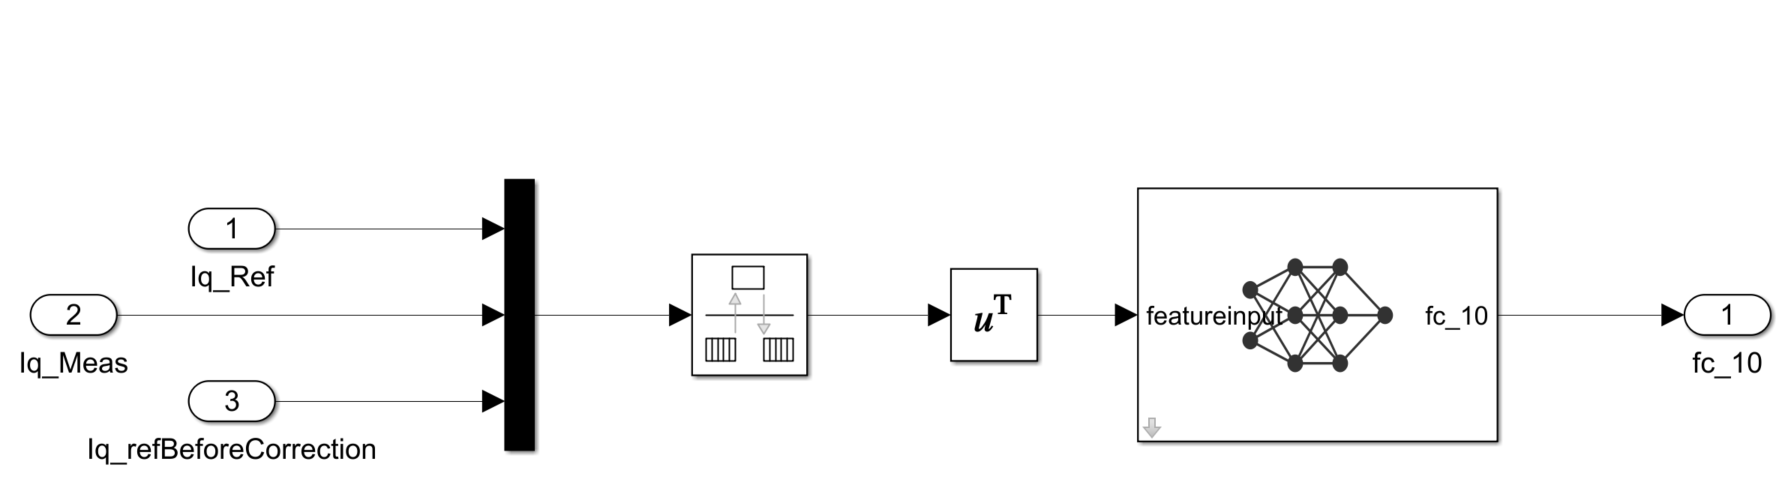

We can open the detailed Simulink model and simulate to collect data of interests to train neural networks.

% points to the focus
load_system("FOCforPMSM_NNAugmented"); 
open_system("FOCforPMSM_NNAugmented/FOC/Current Control/Current_Controllers/PI_Controller_Iq/Subsystem"); 
simOutput = sim("FOCforPMSM_NNAugmented"); 
disp(simOutput.logsout);

## Export network to Simulink blocks using library implementations

Generate Simulink model that contains deep learning layer blocks that correspond to deep learning layer objects. 

load("tnetSaved.mat"); 
mdlInfo = exportNetworkToSimulink(tnet); 

We can open a different model using this construct.

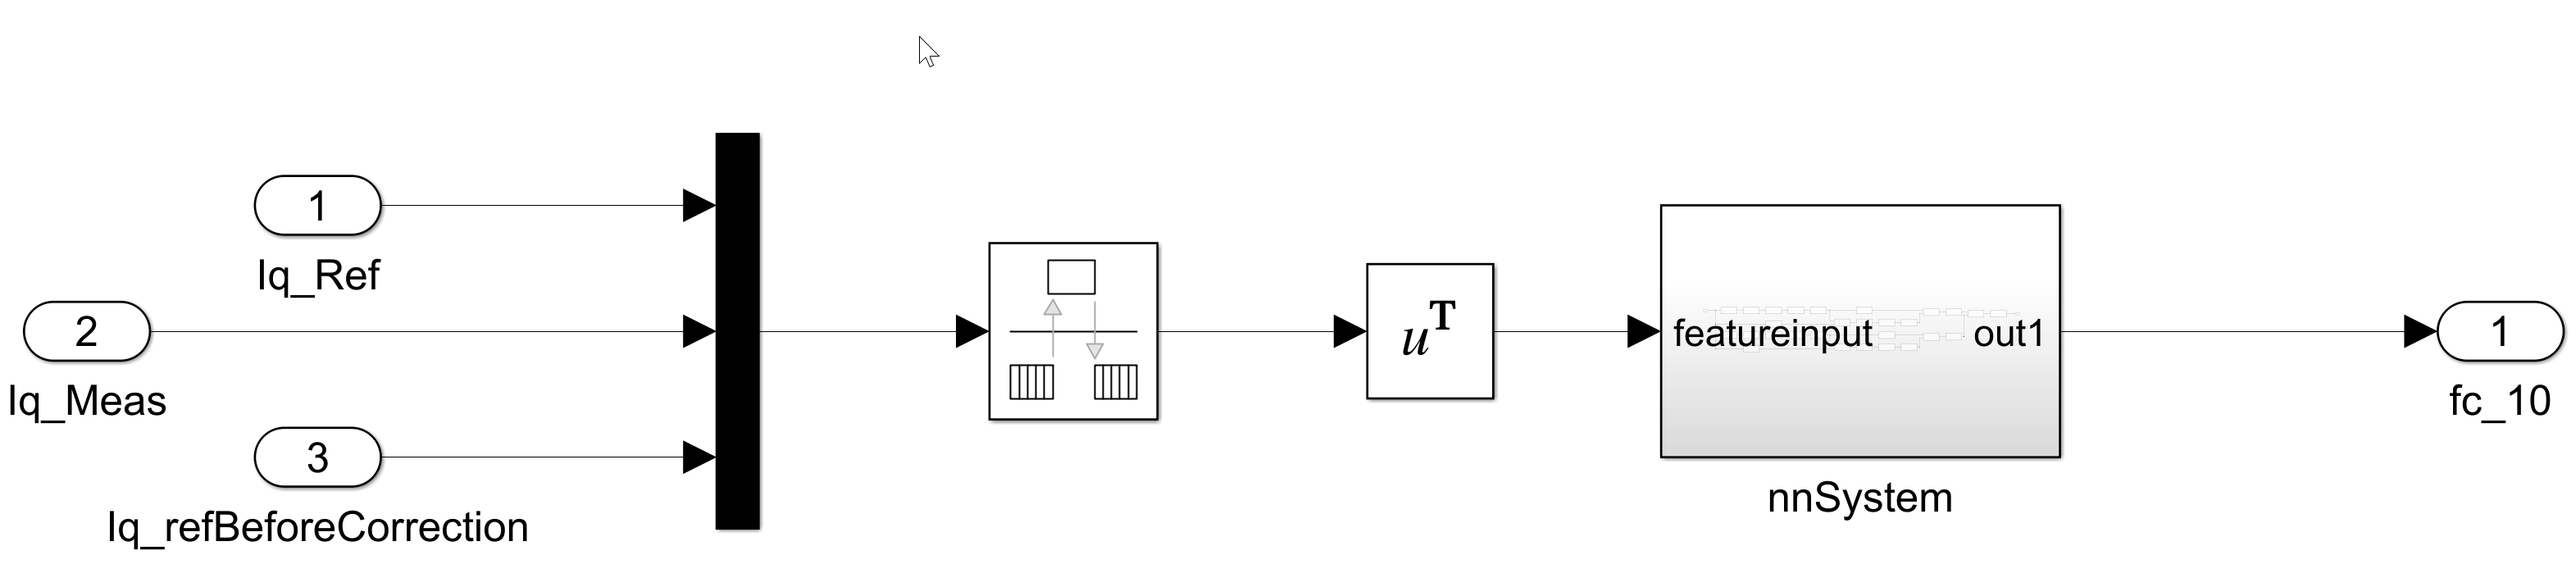

load_system("FOCforPMSM_DLBlocks"); 
open_system("FOCforPMSM_DLBlocks/FOC/Current Control/Current_Controllers/PI_Controller_Iq/Subsystem"); 
simOutput_NNBlock = sim("FOCforPMSM_DLBlocks"); 
disp(simOutput_NNBlock.logsout);